# Problem 3

clear;close;clc;
A = [-.0284, 6.6202, 0, -32.1890; -.0002, -.9542, .9942, -.012; .0013, -7.3610, -1.3895, .0005; 0, 0, 1, 0]

A =    -0.0284    6.6202         0  -32.1890
   -0.0002   -0.9542    0.9942   -0.0120
    0.0013   -7.3610   -1.3895    0.0005
         0         0    1.0000         0


B = [0; -.0748; -15.0071; 0]

B =          0
   -0.0748
  -15.0071
         0


C = eye(4)

C =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


D = zeros(4,1)

D =      0
     0
     0
     0



eA = eigs(A)

eA =   -1.1763 + 2.6967i
  -1.1763 - 2.6967i
  -0.0097 + 0.0986i
  -0.0097 - 0.0986i


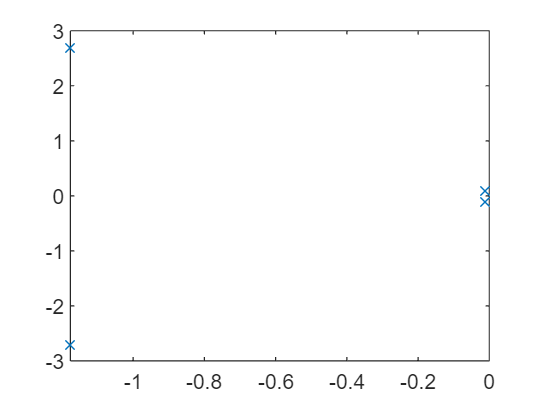

plot(eA,"x")


[n,d] = ss2tf(A,B,C,D)

n =          0         0   -0.4952  383.6017  444.4083
         0   -0.0748  -15.0261   -0.2466   -0.0946
         0  -15.0071  -14.1954   -0.4116    0.0000
         0         0  -15.0071  -14.1954   -0.4116


d =     1.0000    2.3721    8.7116    0.1918    0.0849


theta_delta_e = tf(n(4,:),d)

theta_delta_e =
 
           -15.01 s^2 - 14.2 s - 0.4116
  -----------------------------------------------
  s^4 + 2.372 s^3 + 8.712 s^2 + 0.1918 s + 0.0849
 
Continuous-time transfer function.



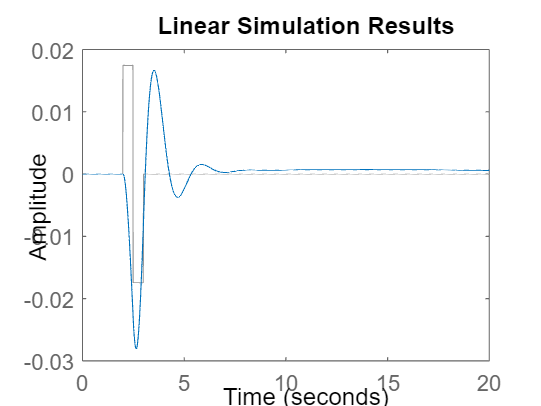


endTime = 20;
step = .01;

time = 0:step:endTime;
doublet = zeros(size(time));
singlet = zeros(size(time));

singlet(2/step:2.5/step) = -ones(size(2/step:2.5/step));

doublet(2/step:2.5/step) = ones(size(2/step:2.5/step));
doublet(2.5/step:3/step) = -1*ones(size(2.5/step:3/step));

% lsim(theta_delta_e,deg2rad(1)*doublet,time)

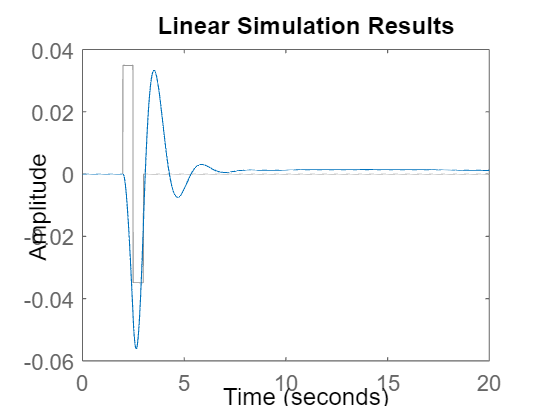

% lsim(theta_delta_e,deg2rad(2)*doublet,time)

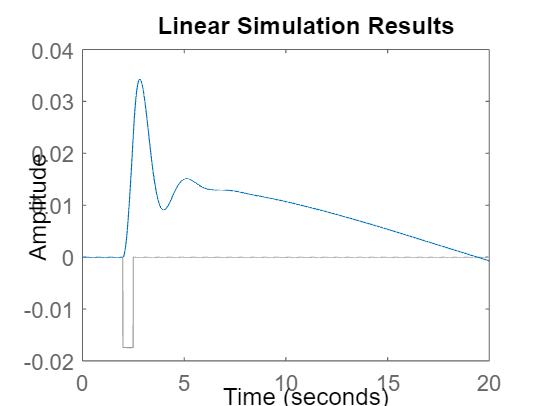

% lsim(theta_delta_e,deg2rad(1)*singlet,time)

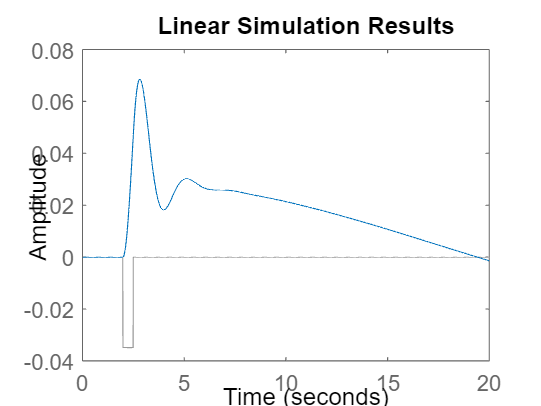

% lsim(theta_delta_e,deg2rad(2)*singlet,time)

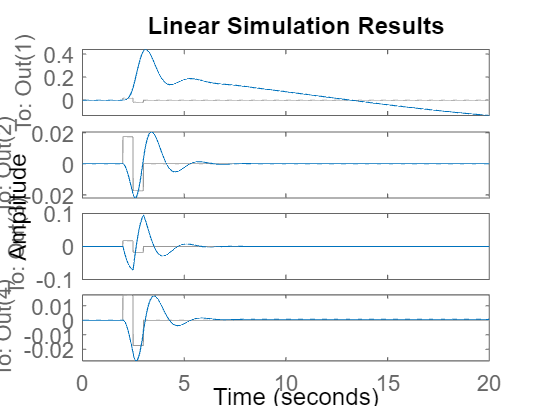


%fig 1 response of state space system (as given in problem)
%for responses that converge within 20s
lsim(ss(A,B,C,D),deg2rad(1)*doublet,time)

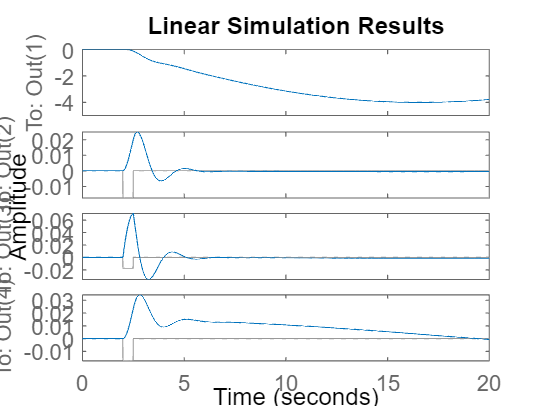

lsim(ss(A,B,C,D),deg2rad(1)*singlet,time)

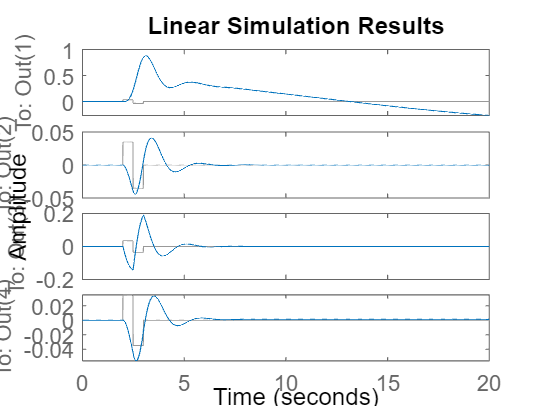


%fig 2 response of state space system (as given in problem)
%for responses that converge within 20s
lsim(ss(A,B,C,D),deg2rad(2)*doublet,time)

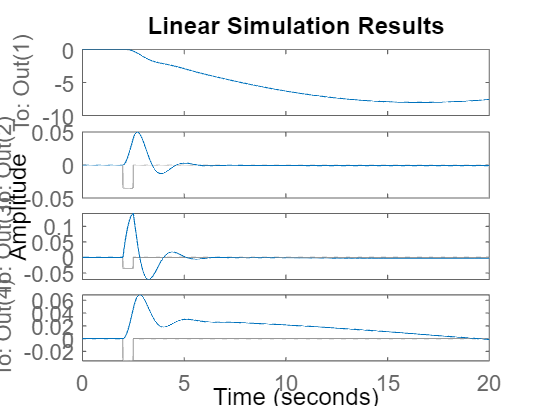

lsim(ss(A,B,C,D),deg2rad(2)*singlet,time)

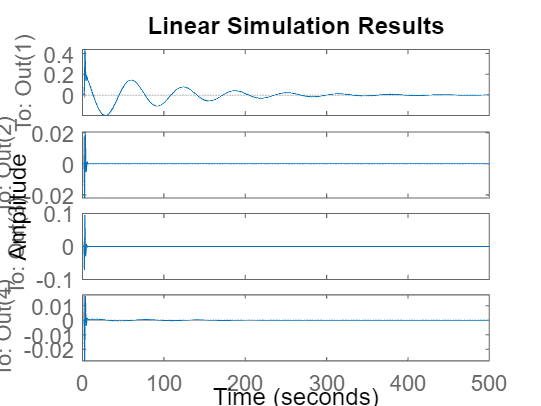



endTime = 500;
step = .01;

time = 0:step:endTime;
doublet = zeros(size(time));
singlet = zeros(size(time));

singlet(2/step:2.5/step) = -ones(size(2/step:2.5/step));

doublet(2/step:2.5/step) = ones(size(2/step:2.5/step));
doublet(2.5/step:3/step) = -1*ones(size(2.5/step:3/step));

%fig 3 response of state space system (as given in problem)
%for responses that converge within 500s
lsim(ss(A,B,C,D),deg2rad(1)*doublet,time)

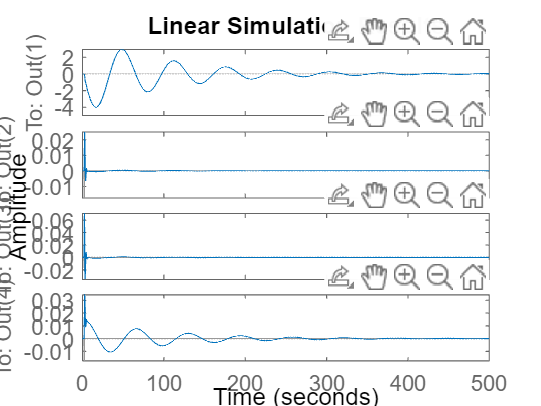

lsim(ss(A,B,C,D),deg2rad(1)*singlet,time)

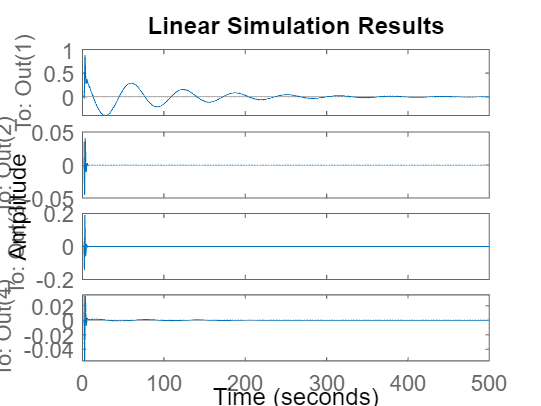


%fig 4 response of state space system (as given in problem)
%for responses that converge within 500s
lsim(ss(A,B,C,D),deg2rad(2)*doublet,time)

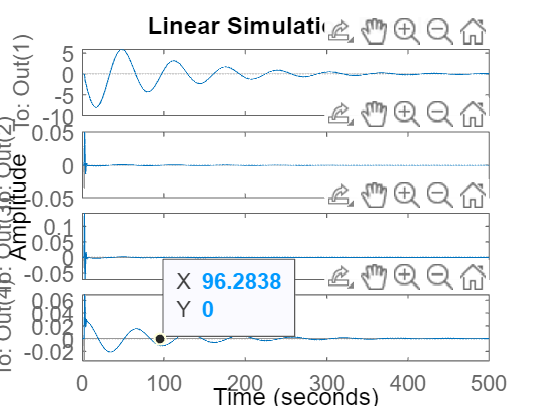

lsim(ss(A,B,C,D),deg2rad(2)*singlet,time)